M = 64;
K = 72;
L = 13;

R = 200;
r = sqrt(3)/2*R;

theta_0 = pi/12;
max_theta = pi/6;


$$r_{12} = \frac{ | \mathbf{h}_{1}^{\mathrm{H}} \mathbf{h}_{2} | }{ \Vert \mathbf{h}_{1} \Vert_{2} \Vert \mathbf{h}_{2} \Vert_{2} }$$



$$r_{12} = \frac{1}{M} \left | \mathrm{e}^{ -\mathrm{j}(\phi_{1} - \phi_{2})} \left [ \frac{1 - \mathrm{e}^{\mathrm{j}M\pi (\sin\theta_{1} - \sin\theta_{2})}}{1 - \mathrm{e}^{\mathrm{j}\pi (\sin\theta_{1} - \sin\theta_{2})}} \right]  \right|$$



$$r_{12} = \frac{1}{M} \left | \frac{\mathrm{e}^{\mathrm{j} M \frac{\pi}{2} (\sin\theta_{1} - \sin\theta_{2})}}{\mathrm{e}^{\mathrm{j}\frac{\pi}{2} (\sin\theta_{1} - \sin\theta_{2})}} \left [ \frac{\mathrm{e}^{\mathrm{j} M \frac{\pi}{2} (\sin\theta_{1} - \sin\theta_{2})} - \mathrm{e}^{-\mathrm{j} M \frac{\pi}{2} (\sin\theta_{1} - \sin\theta_{2})}}{\mathrm{e}^{\mathrm{j}\frac{\pi}{2} (\sin\theta_{1} - \sin\theta_{2})} - \mathrm{e}^{-\mathrm{j}\frac{\pi}{2} (\sin\theta_{1} - \sin\theta_{2})}} \right]  \right|$$



$$r_{12} = \frac{1}{M} \left | \frac{\sin \left( M \frac{\pi}{2} (\sin\theta_{1} - \sin\theta_{2}) \right) }{\sin \left( \frac{\pi}{2} (\sin\theta_{1} - \sin\theta_{2}) \right)} \right|$$


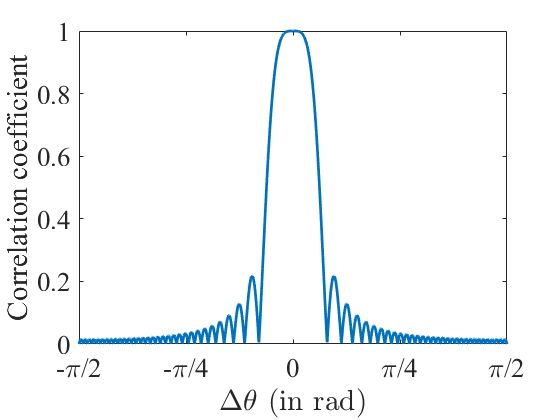

d_theta = -pi/2:pi/1800:pi/2;
% d_theta = 0:pi/1800:2*pi;

theta_1 = pi/2;
theta_2 = theta_1 + d_theta;

r_12 = abs(sin(M*pi/2*(sin(theta_1) - sin(theta_2)))./sin(pi/2*(sin(theta_1) - sin(theta_2))))/M;

linewidth  = 2;
fontname   = 'TImes New Roman';
fontsize   = 20;
markersize = 10;

plot(d_theta,r_12,'linewidth',linewidth);
% plot(theta_2,r_12,'linewidth',linewidth);

xlabel('$\Delta\theta$ (in rad)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
ylabel('Correlation coefficient','fontname',fontname,'fontsize',fontsize);

xticks([-pi/2 -pi/4 0 pi/4 pi/2])
xticklabels({'-\pi/2','-\pi/4','0','\pi/4','\pi/2'});
set(gca,'fontname',fontname,'fontsize',fontsize);
xlim([-pi/2 pi/2]);
ylim([0 1]);

x_cell = [R R/2 -R/2 -R -R/2 R/2 R]';                                % Cell's x-coordinates
y_cell = [0 r    r    0 -r  -r   0]';                                % Cell's y-coordinates

radius = r*sqrt(rand(K,1));
theta  = theta_0 +  max_theta*rand(K,1);

x = radius.*cos(theta);
y = radius.*sin(theta);

N_CIRCLE_POINTS = 100;

theta_circle  = theta_0 + max_theta*linspace(0,1,N_CIRCLE_POINTS);

x_circle = r*cos(theta_circle);
y_circle = r*sin(theta_circle);

# Ploting Cell and Users Distribution

## Ploting Parameters

linewidth  = 2;
fontname   = 'TImes New Roman';
fontsize   = 20;
markersize = 10;

## Distribution of the Users in a Small Piece of the Cell

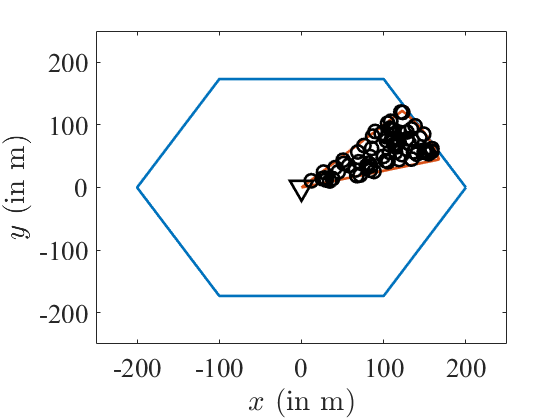

plot(x_cell,y_cell,'linewidth',linewidth);
hold on;
plot([0 x_circle 0],[0 y_circle 0],'linewidth',linewidth);
plot(0,0,'vk','linewidth',linewidth,'markersize',1.5*markersize);
plot(x,y,'ok','linewidth',linewidth,'markersize',markersize);
xlabel('$x$ (in m)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
ylabel('$y$ (in m)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');

set(gca,'fontname',fontname,'fontsize',fontsize);
xlim([-1.25*R 1.25*R]);
ylim([-1.25*R 1.25*R]);